# **Task 3: Generate C Code for Edge Deployment**

In this task, you will use Simulink to generate C code for the compressed AI models. You will also practice integrate the AI model into Simulink for simulation. The final part involves performance profiling, where you will compare the execution time of the generated code for both models, providing insights into the efficiency improvements achieved through model compression. This exercise is designed to equip you with practical skills in model optimization, code generation, and performance analysis, essential for deploying efficient deep learning models in real-world applications.

Now that we have successfully compressed a deep neural network for bearing fault diagnosis, we would like to generate C code to deploy to an embedded system.

## 1. Export the AI Model to Simulink

Load the quantized network.

load("quantized_net.mat")

Export the network to Simulink as Layer Block is one way to generate C code for a neural network. FrameBased is enabled since the input of the network is set as 5000.

exportNetworkToSimulink(quantizedNet,"ModelName","quantizedNetSim","FrameBased",true);

Once the network is exported to Simulink, you can click Update Model in COMPILE tab in DEBUG.

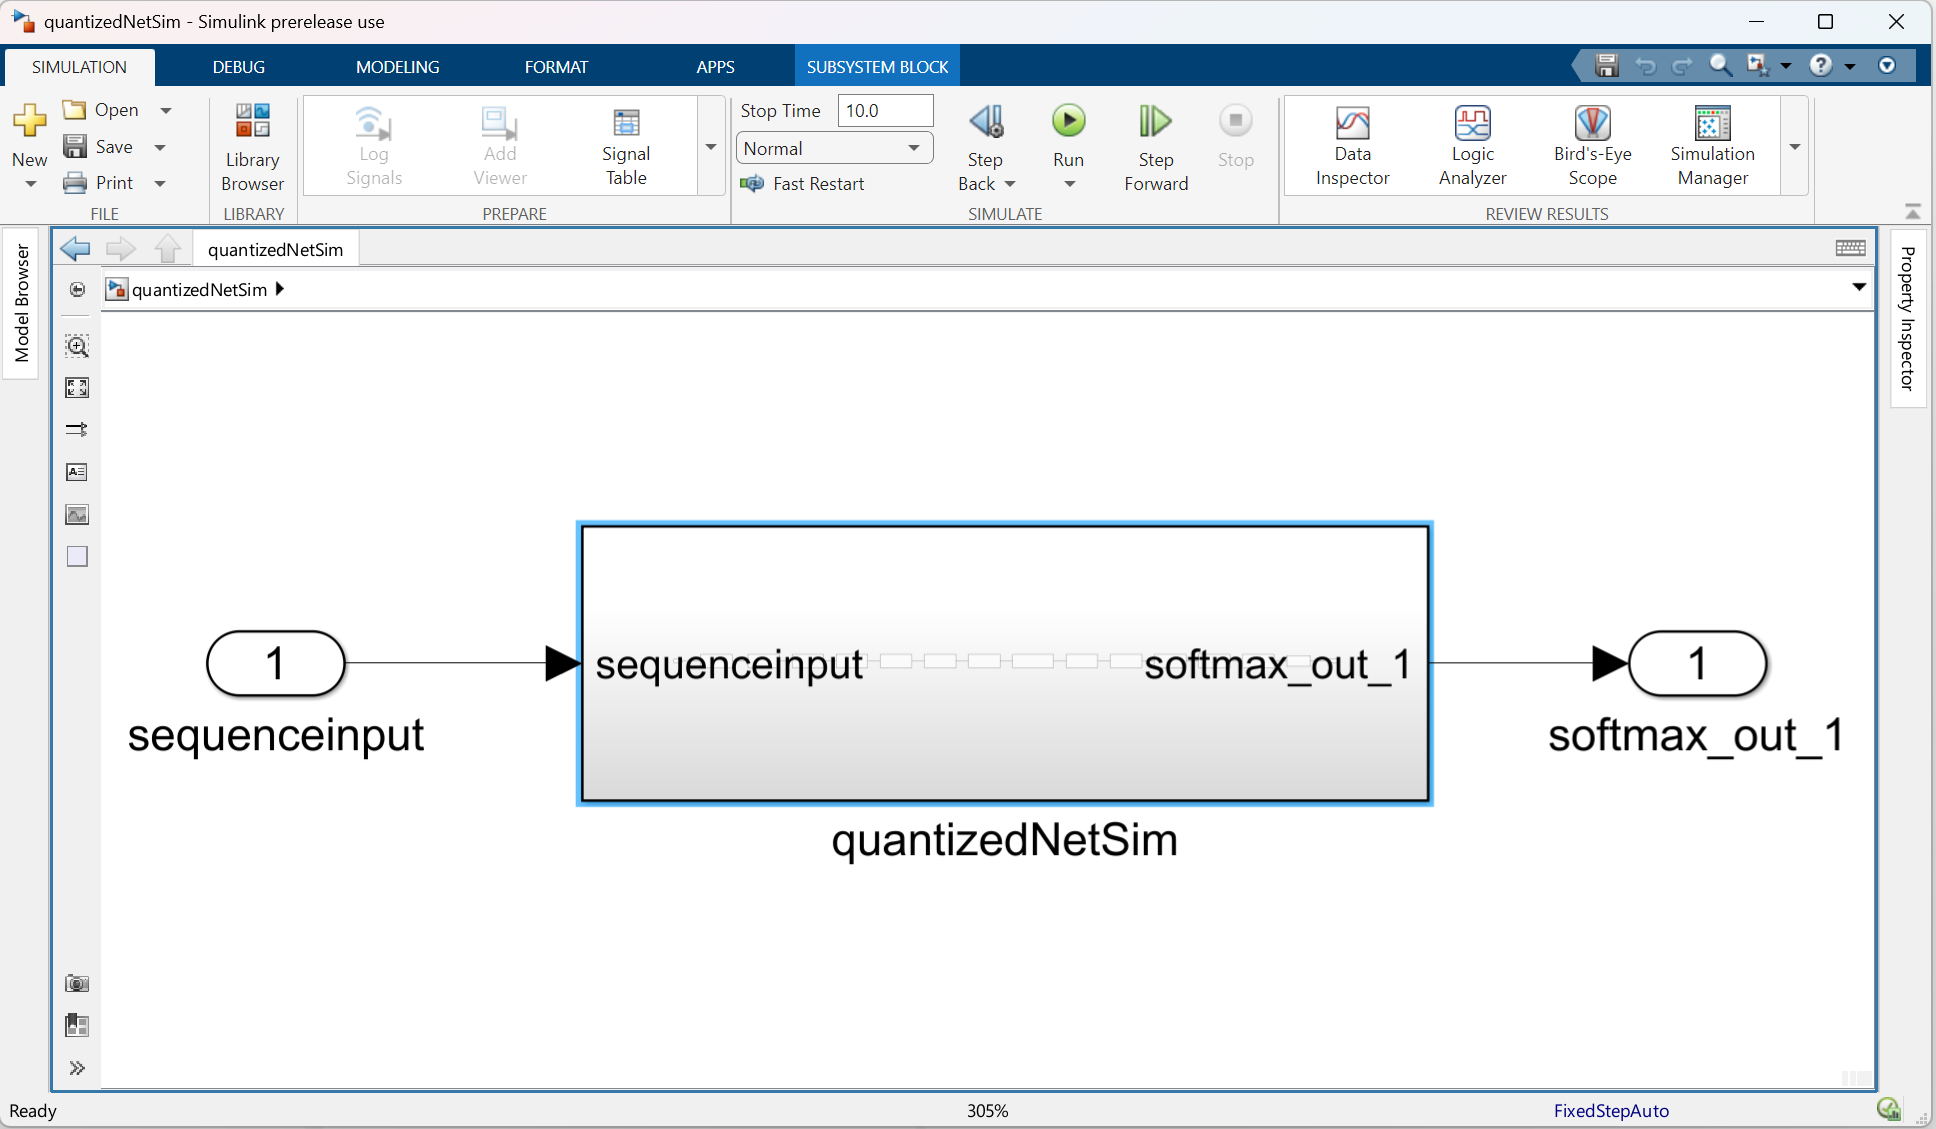

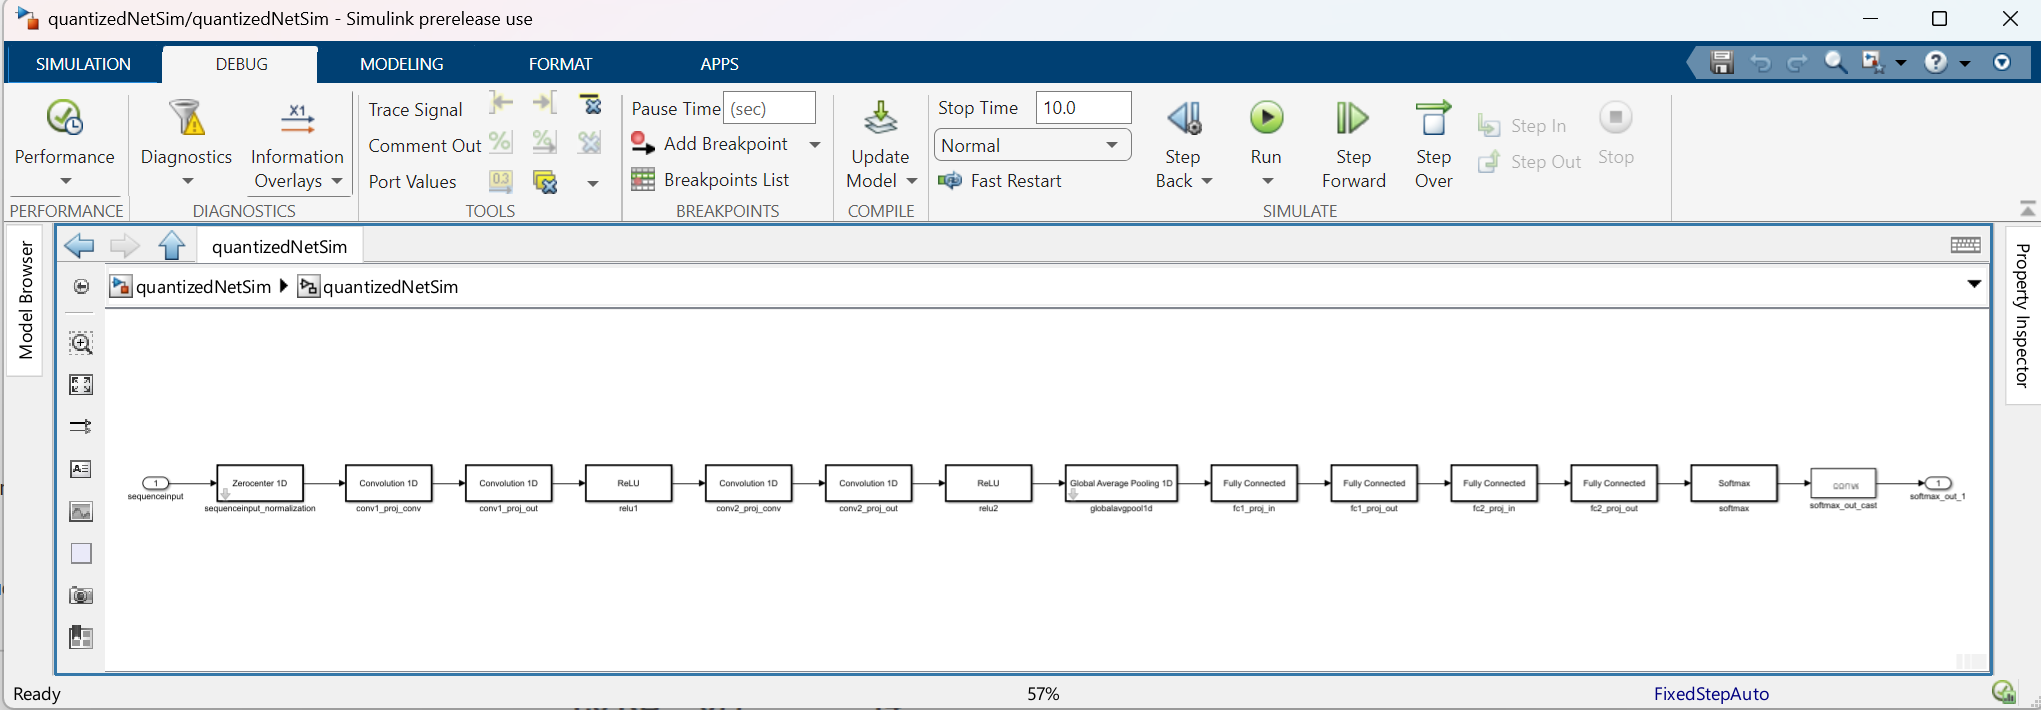

## 2. Simulate the AI Model in Simulink (Optional for Code Generation)

Load and preprocessing testing data. Stitch 3 frames of raw data representing each condition for simulation,

load("trainTable.mat")
load("testTable.mat")
% Prepare Data
allTrainData = cell2mat(trainTable{:,4});
muTrain = table2array(mean(allTrainData));
sigmaTrain = table2array(std(allTrainData));
% Get Testing Data and Normalize
XTest = cell2mat(cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(testTable(:,4)),'UniformOutput',false)');
YTest = categorical(string(testTable.label));
Ts = 1;
tstop = 3*size(XTest,1)-1;
timeVector = (0:Ts:tstop)';
inputs = [timeVector, reshape(XTest(:,[1,50,80]),[],1)];

Open Simulink Model and replace the quantizedNetSim block with the new one.

open_system("simulateAIModel_R2025a")

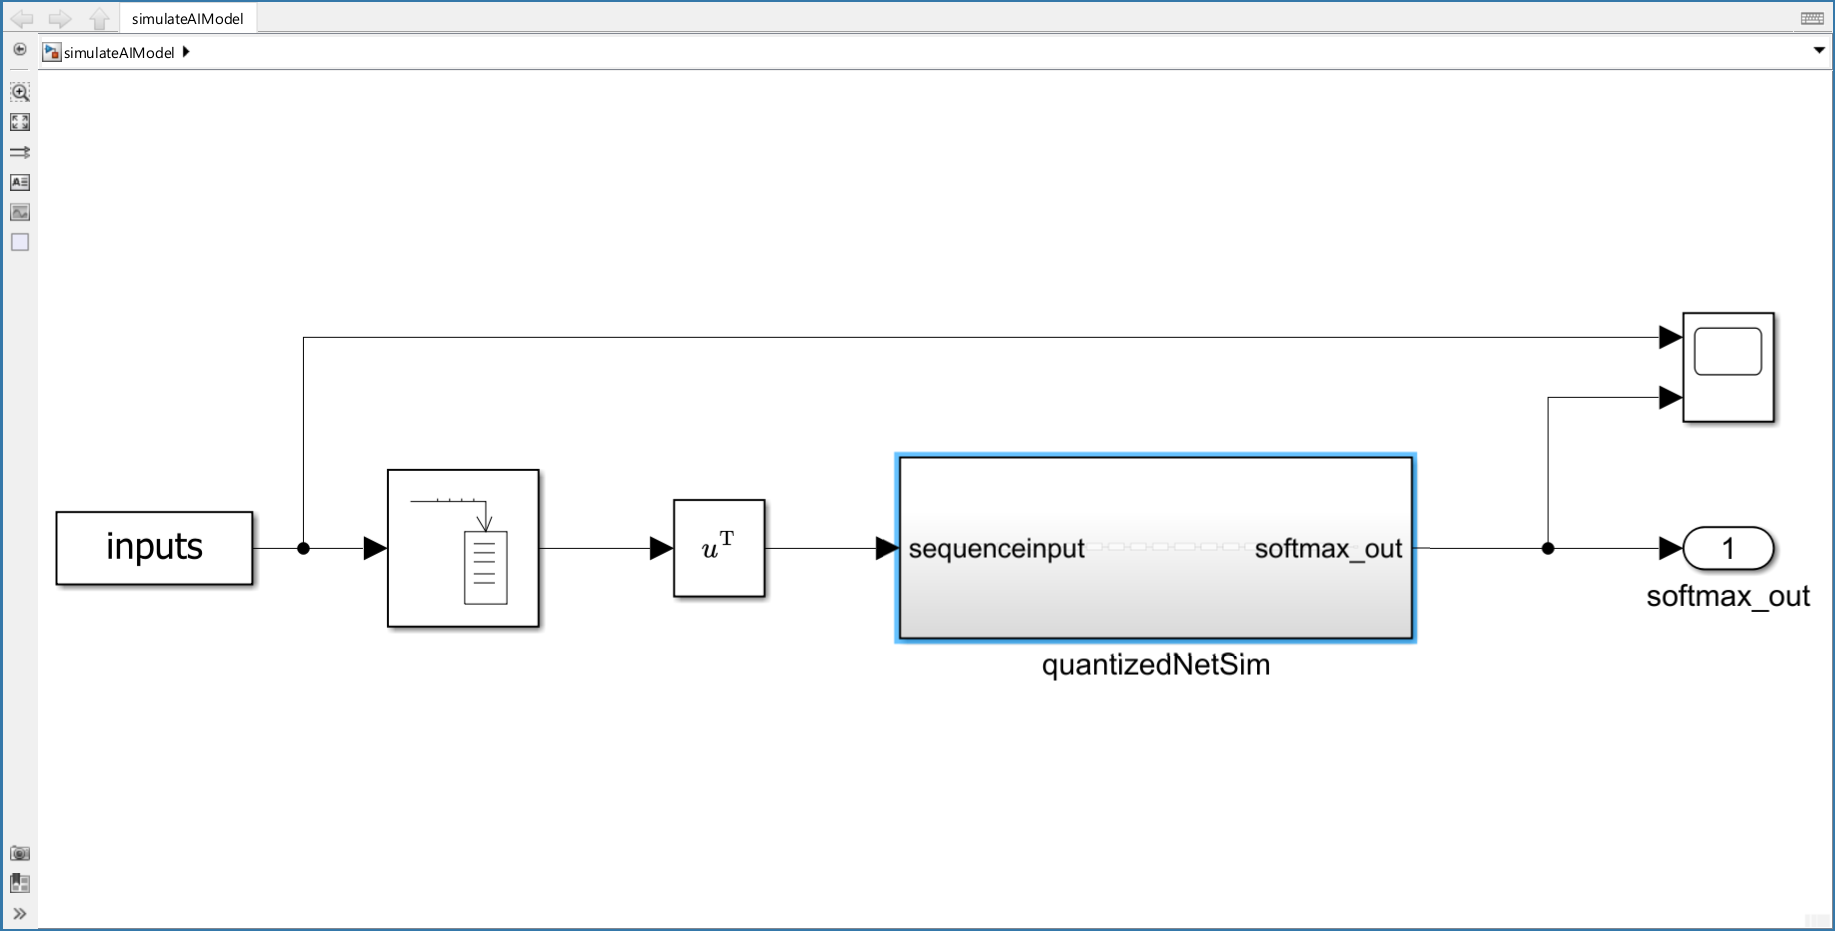

Simulate the Open-Loop Model and check output from the Scope.

simOut = sim("simulateAIModel_R2025a");

## 3. Generate C Code using Embedded Coder

Open Embedded Coder from the APPS tab.

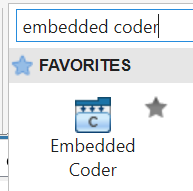

Click Quick Start and follow steps through to select options fit for your purpose. In this exercise, you can choose C code and Single instance in the Output section. Then choose ARM Compatible for Device Vendor and ARM Cortex-M for Device Type in the Word Size section. Choose Execution efficiency in Optimization. You will see some settings are changed due to this selection.

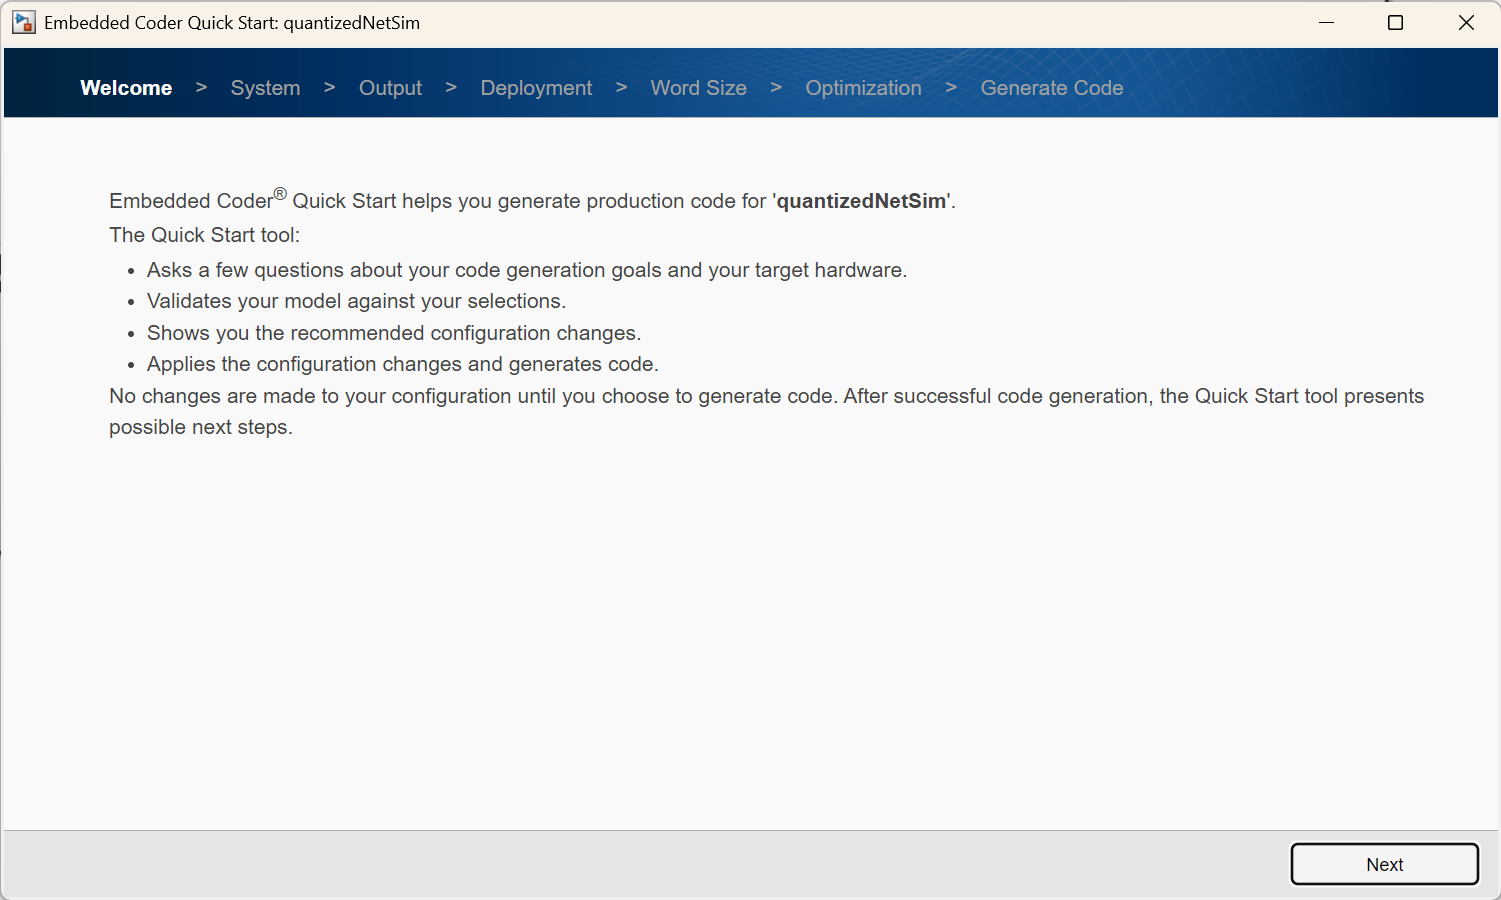

Once the code generation finished, you can click on Open Report to check the generated code.

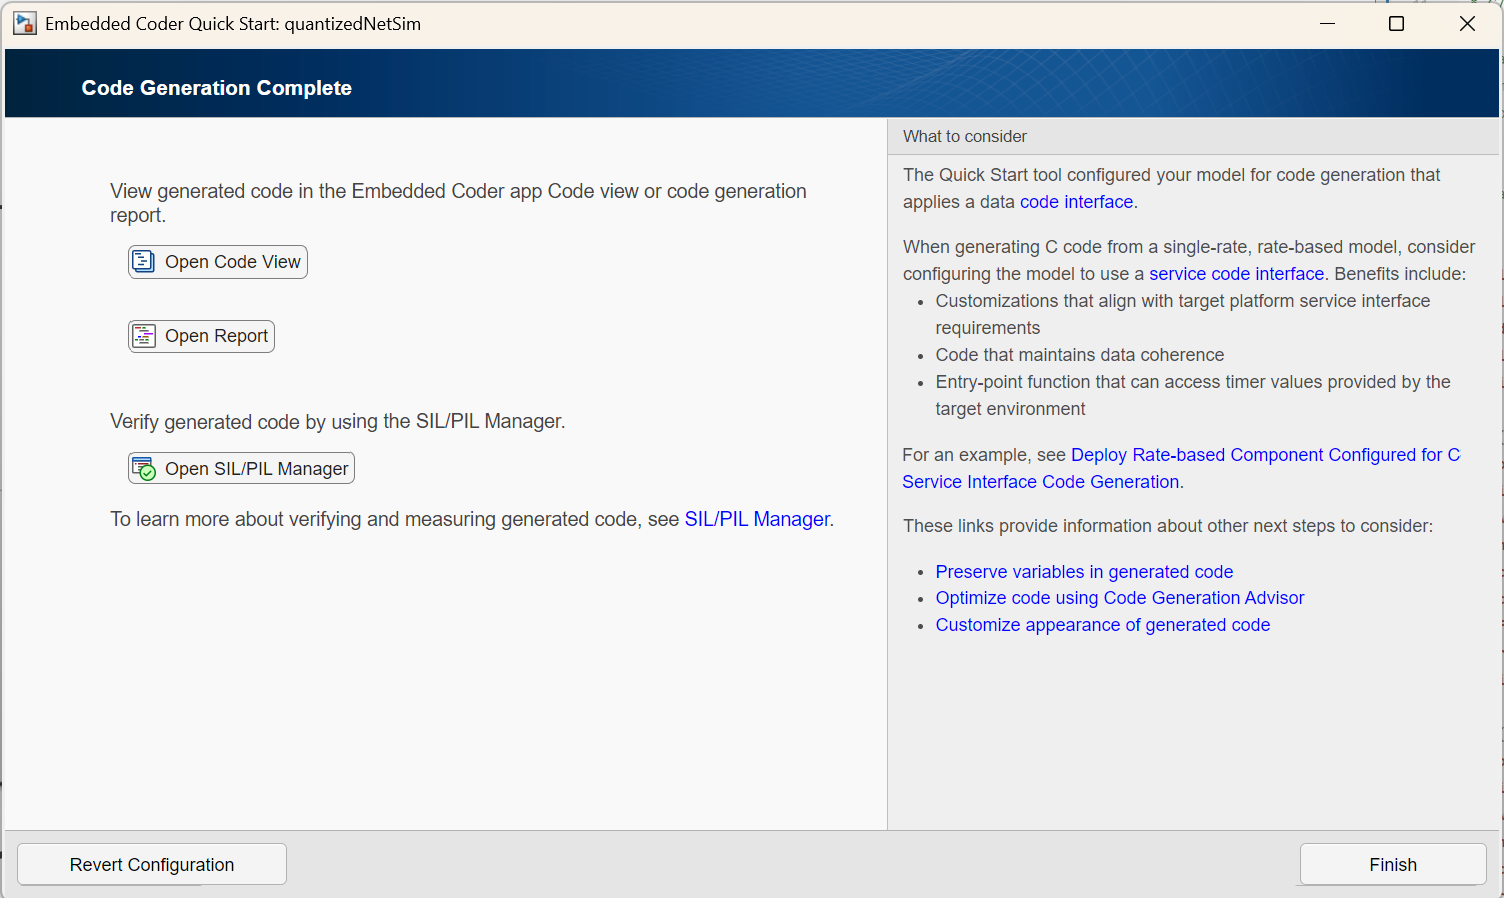

You can find the generated C files and H files. The model weights, forward path are easy to find in the files. Now you can flash the generated files and dependencies to the edge device.